clear
clc
close all

format bank

%%%% Wing Cube Loading: for trainers: 5 to 7
WCL = 7;

%%%Weight Estimate (oz)
weight_servo = 1.763698;
weight_battery = 4.232875; %%
weight_esc = 0.07; %%%  Power supply 
weight_motor = 17.63698; %% and propulsion
weight_prop = 2.116438; %% Thrust
weight_receiver = 2.998287;
weight_control_horns_rods = 2.116438;
weight_fuselage = 0.811301;
weight_wing = 70.54792;
weight_payload = 176.3698;
weight = (weight_wing+weight_payload+weight_servo+weight_battery+weight_esc+weight_motor+weight_prop+weight_receiver+weight_control_horns_rods+weight_fuselage);
weight_lbf = weight/16;
weight_SI = weight/35.274;

disp(['Weight = ',num2str(weight),' oz'])

Weight = 278.6637 oz


disp(['Weight = ',num2str(weight_SI),' kg'])

Weight = 7.9 kg




%%% A typical trainer has thrust to weight ratio from 0.5 to 0.8, hence-
TW = 0.8;
Thrust = TW*weight

Thrust =         222.93


Thrust_kg = 0.8*10 % approximated total wt in kg = 10

Thrust_kg =           8.00




%%% Using the above thrust value - find motor spec online that'll provide
%%% the required thrust -> Find weight of motor -> iterate and settle to a
%%% value of motor, battery and thrust value. 

%%% Computing S from WCL = W/S^(3/2) 
S_sqft = (weight/WCL)^(2/3);
S_SI = S_sqft/10.764

S_SI =           1.08



%%% Choosing Aspect Ratio: For typical trainer its approx 7.32
AR = 7.32;
disp(['Aspect ratio = ',num2str(AR)])

Aspect ratio = 7.32



%%% Computing Wingspan 
b = sqrt(AR*S_sqft);
b_SI = b/3.281;
disp(['Wingspan = ',num2str(b_SI),' m'])

Wingspan = 2.8156 m



%%% Can compute chord now
c = S_sqft/b;
c_SI = c/3.281;
disp(['chord = ',num2str(c_SI),' m'])

chord = 0.38465 m


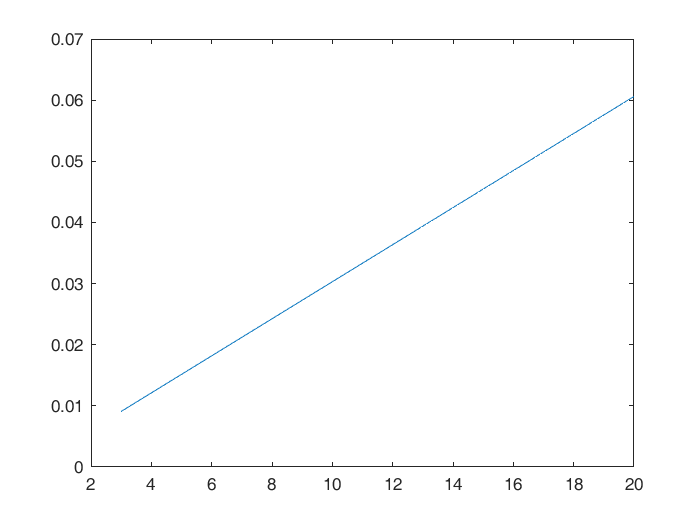


%%% Flight regime
V_SI = linspace(3,20,100); %%% m/s
V = V_SI*3.281; %%% ft/s

%%% Density at altitude
rho_SI = 1.225; %%%kg/m^3
rho = 0.002378; %%%slugs/ft^3

%%% Computing Re
mu = 1.81e-5; %%%SI units
% format long g
Re = rho_SI * V_SI * c_SI / mu;

%%% Mach Number
a_inf = 330;
M = V_SI/a_inf;

figure()
plot(V_SI,M)

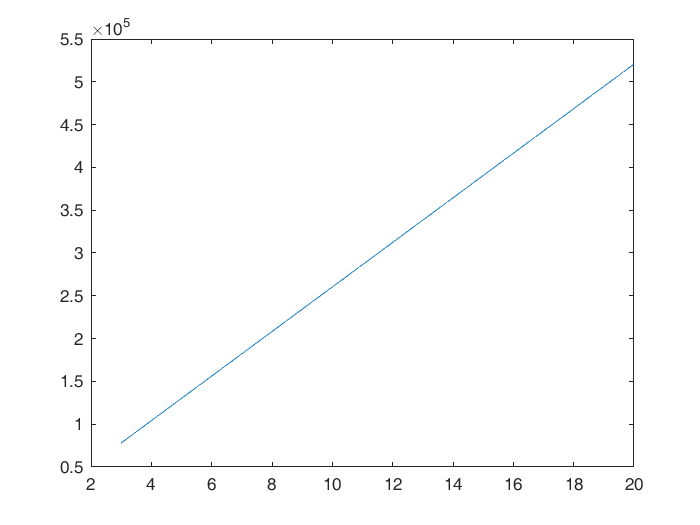

figure()
plot(V_SI,Re)


%%% MACH and RE NUMBER FOR XFLR5
%%% M = 0.06
%%% Re = 520818

%%% Pick an Airfoil
%%% Assume Re is between 400000 and 520000

%%% Estimate alpha0, Cla from XFLR5 and find CLA
alpha0 = -5.97831*pi/180; %%% ZERO LIFT AOA
alpha0_deg = alpha0*180/pi

alpha0_deg =          -5.98


Cla = 0.61141/(-alpha0) %%% Lift curve slope

Cla =           5.86



%%% Finding Lift Curve Slope of the wing 
e = 0.9; %%% Efficiency
CLA = Cla/(1+Cla/(pi*e*AR))

CLA =           4.57


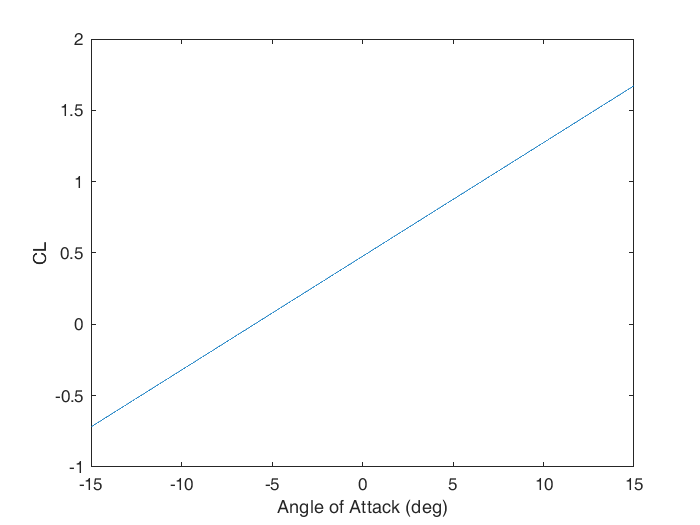

CLA_deg = CLA*pi/180;

%%% Now we can plot CL vs Alpha [not perfect, there are deviations from
%%% actual CL vs alpha due to slope irregularities)
alpha_deg = linspace(-15,15,1000);
alpha = alpha_deg*pi/180;
CL = CLA_deg*(alpha_deg-alpha0_deg);

figure()
plot(alpha_deg,CL)
xlabel('Angle of Attack (deg)')
ylabel('CL')

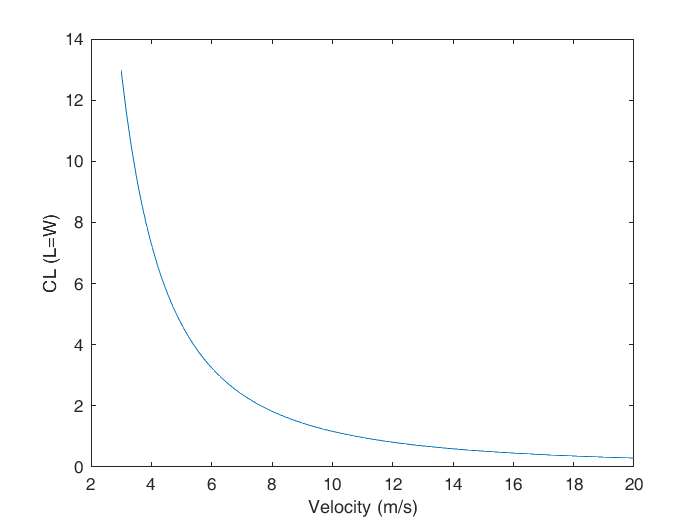


%% Computing Angle of Attack as function of velocity
%%% L = W = 0.5*rho*V^2*S*CL
%%% CL = 2*W/(rho*V^2*S)
CL_req = 2*weight_lbf./(rho*(V.^2)*S_sqft);
figure()
plot(V_SI,CL_req)
xlabel('Velocity (m/s)')
ylabel('CL (L=W)')

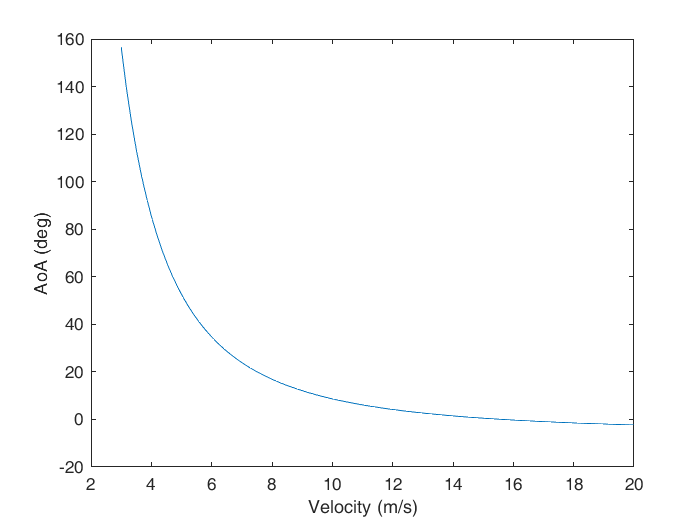

%%% From graph (for the given specs of UAV) we can see that to fly around a speed of 15 m/s to 20 m/s,
%%% we only require lift coefficient to be from 0 to 1 -> desirable 

AoA_req_deg = CL_req/CLA_deg + alpha0_deg;
AoA_req = AoA_req_deg*pi/180;
figure()
plot(V_SI,AoA_req_deg)
xlabel('Velocity (m/s)')
ylabel('AoA (deg)')

%%% From the graph (for the given specs of UAV) we can see that the angle
%%% of attack required is 0 for the assumed cruise speed 15 m/s


%%% To find the thrust required for a given flight speed, we plot drag vs
%%% angle of attack
Cd0 = 0.01597; %%%drag coefficient at zero lift
Cd2 = 0.037;

%%% Now we can compute Wing Drag Coefficients
CD0 = Cd0/(1+Cd0/(pi*e*AR))

CD0 =           0.02


CD2 = Cd2/(1+Cd2/(pi*e*AR))

CD2 =           0.04


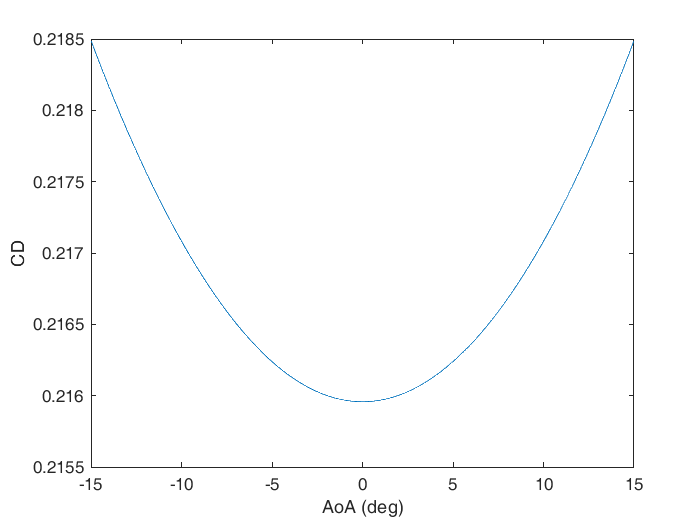

CDf = 0.2; %%% Fuselage drag cannot be mathematically computed, assumed value is completely random (get this from another program. SolidWorks, DATCOMM)

%%% Computing CD
CD = CD0 + CD2*alpha.^2 + CDf;

figure()
plot(alpha_deg,CD)
xlabel('AoA (deg)')
ylabel('CD')

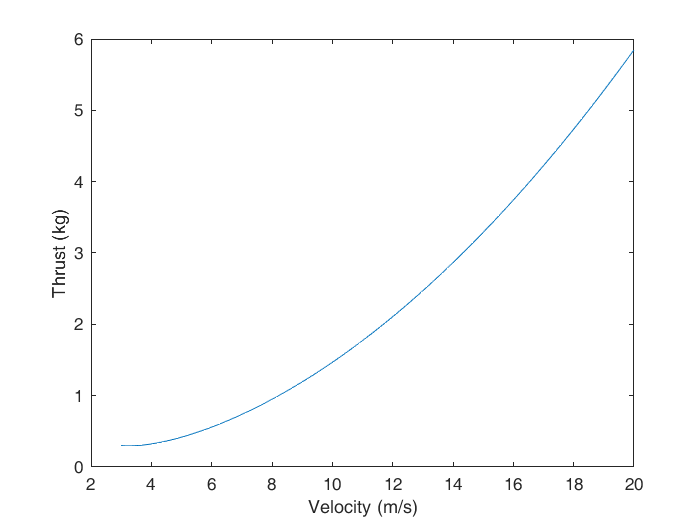


%%%% D = 0.5*rho*V^2*S*CD
%%% Vary flight speed from 3:20 
%%% Compute AoA (done on line 124)
%% Using that AoA computing Cl
Thrust_req = 0.5*rho*V.^2*S_sqft.*(CD0 + CD2*AoA_req.^2 + CDf);
Thrust_req_oz = Thrust_req*16;
Thrust_req_SI = Thrust_req_oz/35.274;

figure()
plot(V_SI,Thrust_req_SI)
xlabel('Velocity (m/s)')
ylabel('Thrust (kg)')